# Procesat d'Imatges II

## Filtrat integratiu

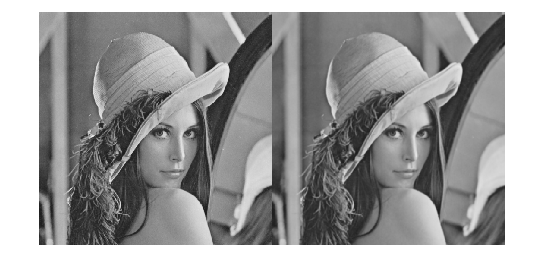

I = imread('lena_gray_512.tif');
% filtre per mitjana
h = [1 1 1; 1 1 1; 1 1 1];
h = h/sum(h, 'all');
J = imfilter(I, h);
montage({I, J});

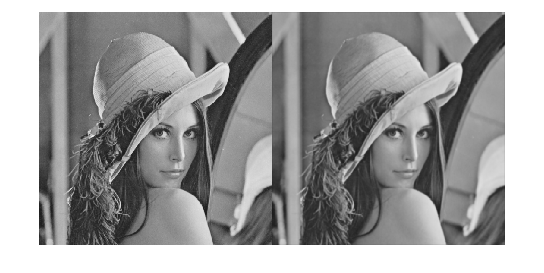

% filtre Gaussià
h2 = fspecial("gaussian", 5, 5/5);
J2 = imfilter(I, h2);
montage({I, J2});

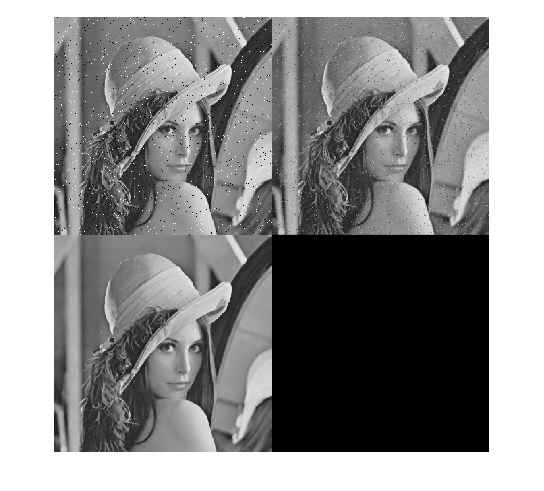

% filtre no lineal
In = imnoise(I, "salt & pepper", 0.02);
h3 = fspecial("gaussian", 3, 3/5); % filtre mitjana per comparar
J3 = imfilter(In, h3);
J4 = medfilt2(In, [3,3]);
montage({In, J3, J4});

## Filtrat derivatiu

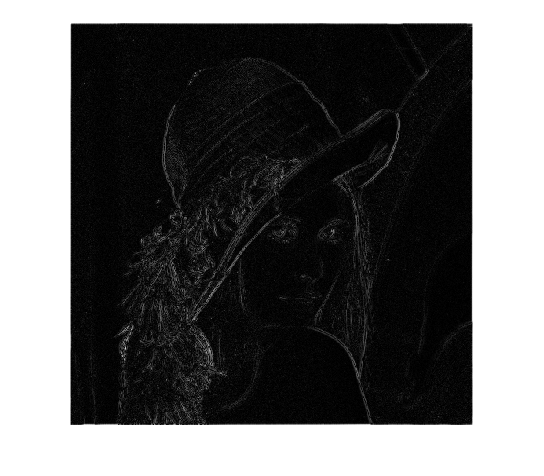

% filtre passa alts
D = abs(double(I) - double(J2));
imshow(D, []);

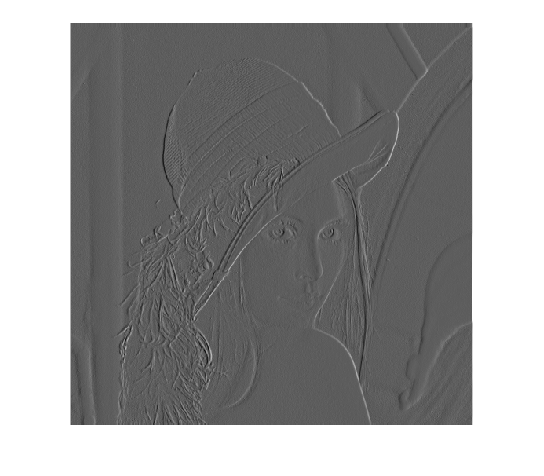

% gradient component x
hx = [1 -1];
Gx = imfilter(double(I), hx);
imshow(Gx,[]);

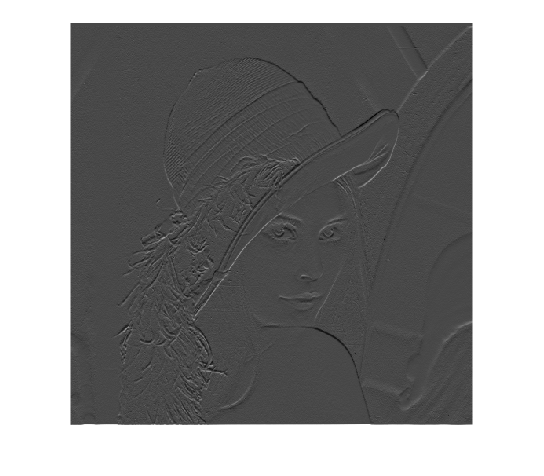

% gradient component y
hy = [1; -1];
Gy = imfilter(double(I), hy);
imshow(Gy,[]);

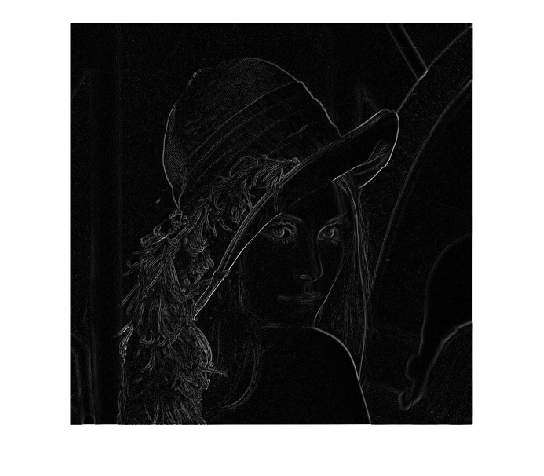

% gradient
Modul = abs(Gx) + abs(Gy);
imshow(Modul,[]);

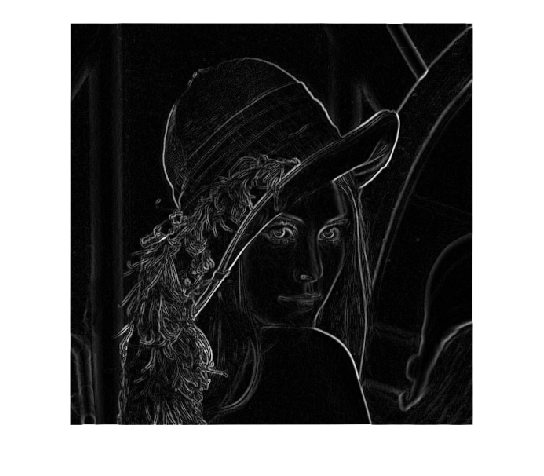

% gradient de Prewitt
hx = [1 0 -1; 1 0 -1; 1 0 -1];
Gx = imfilter(double(I), hx);
hy = hx';
Gy = imfilter(double(I), hy);
Modul = abs(Gx) + abs(Gy);
imshow(Modul,[]);

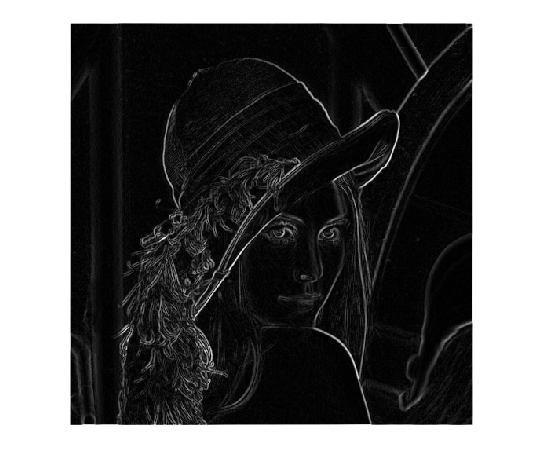

% gradient de Sobel
hx = [1 0 -1; 2 0 -2; 1 0 -1];
Gx = imfilter(double(I), hx);
hy = hx';
Gy = imfilter(double(I), hy);
Modul = abs(Gx) + abs(Gy);
imshow(Modul,[]);

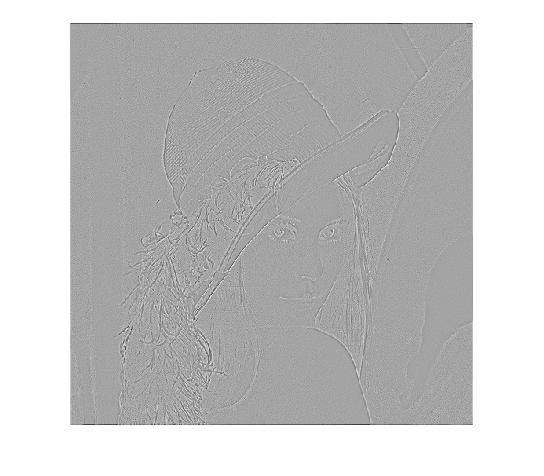

% gradient Laplacià
hl = [0 1 0; 1 -4 1; 0 1 0];
Gl = imfilter(double(I), hl);
imshow(Gl, []);

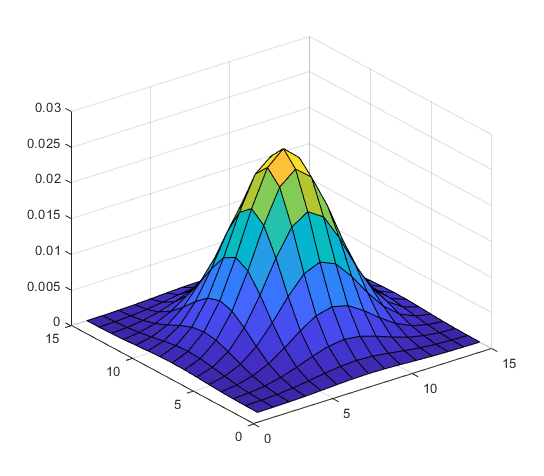

% gradient Lapacià de Gaussià
N = 15;
h = fspecial("gaussian", N, N/6);
[X Y] = meshgrid(1:N, 1:N);
surf(X, Y, h);

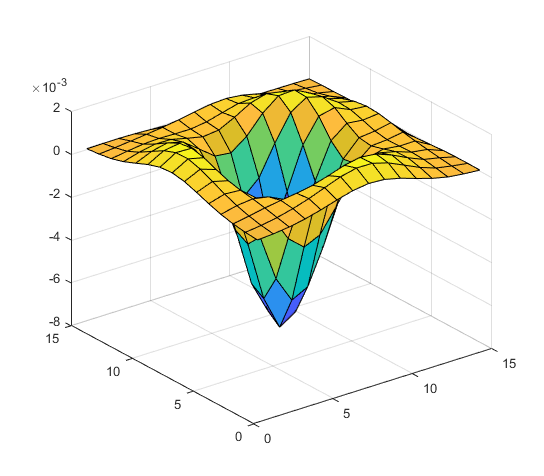

hx = [1 -1];
hy = hx';
dx = imfilter(h, hx, 'replicate');
dy = imfilter(h, hy, 'replicate');
dx2 = imfilter(dx, hx, 'replicate');
dy2 = imfilter(dy, hy, 'replicate');
hl = dx2 + dy2;
surf(X, Y, hl);

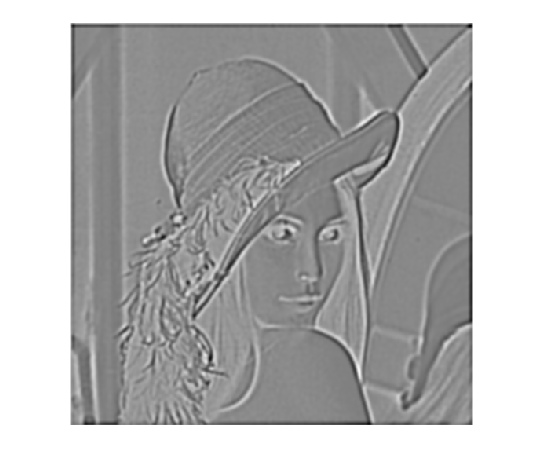

Gl = imfilter(double(I), hl);
imshow(Gl, []);

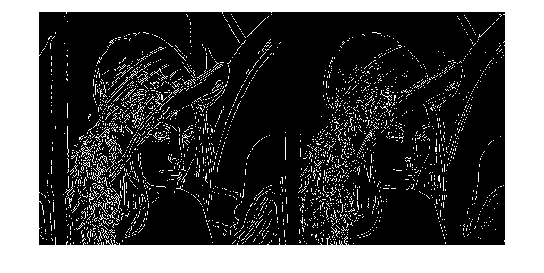

% detecció de contorns per Canny
C = edge(I, "canny"); % aplica algorisme de Canny
Z = edge(I, "zerocross", 0.0035); % detecció de passos per 0, amb llindar d'eliminació de passos per zero poc significatius
montage({C Z});

## Exercici: Equivalencia a color

Una de les opcions seria detectar les vores amb les 3 components del color per separat. Es podrien superposar les 3 imatges resultants per a completar les vores (fent una suma de les 3 imatges).